%%%%%%%%%% 
% Had error in how threshold was being computed and applied to the confusion matrix
% It didnt make sense that reconstruction error was so high for the overall detection of anomalies
% to be so low. 
%%%%%%%%%%
% Compute Reconstruction Errors (MSE)
mseHealthy = mean((testHealthyData - predictedHealthy).^2,2);
mseAnomalous = mean((testAnomalousData - predictedAnomalous).^2,2);

if min(mseErrorAnomalous) > max(mseErrorHealthy)
    threshold = (max(mseErrorHealthy) + min(mseErrorAnomalous)) / 2; 
else
    threshold = (mean(mseErrorHealthy) + mean(mseErrorAnomalous)) / 2; 
end


predictedNormal = mseErrorHealthy >= threshold;  % Normal samples should be below threshold
predictedAbnormal = mseErrorAnomalous >= threshold;  % Anomalous samples should be above threshold

% Combine into predicted labels
predictedLabels = [predictedNormal; predictedAbnormal];
% Define True Labels
trueLabels = [zeros(size(mseErrorHealthy)); ones(size(mseErrorAnomalous))];
trueLabels = logical(trueLabels);
% Generate Confusion Matrix
confMat = confusionmat(trueLabels, predictedLabels);

% Display Confusion Matrix
disp("Confusion Matrix:");

Confusion Matrix:


disp(confMat);

    30     0
     0    30



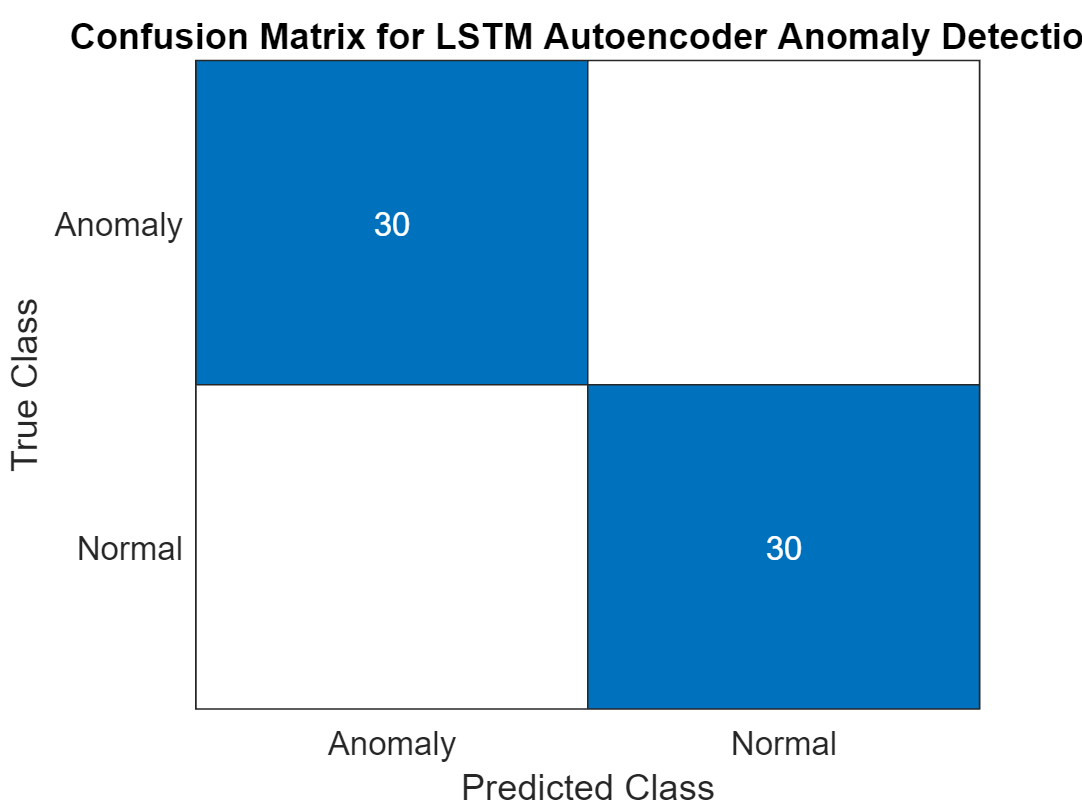


% Plot Confusion Matrix
figure;
confusionchart(confMat, {'Normal', 'Anomaly'});
title("Confusion Matrix for LSTM Autoencoder Anomaly Detection");

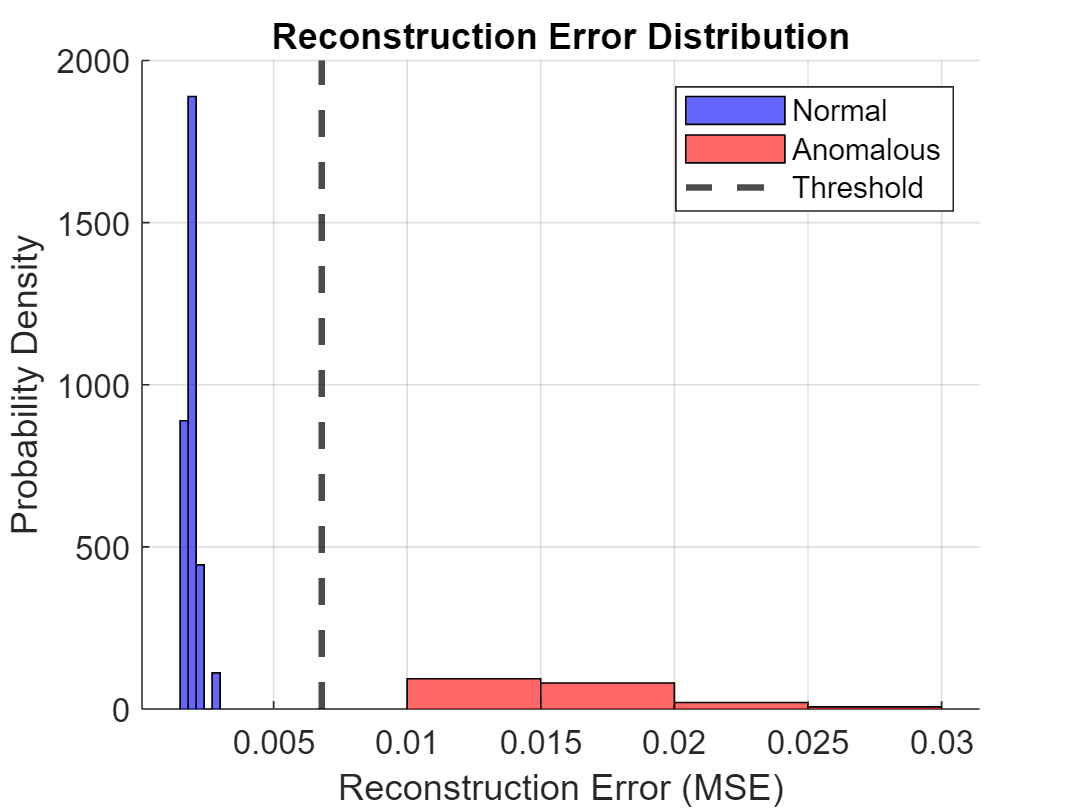


figure;
hold on;
histogram(mseHealthy, 'FaceColor', 'b', 'Normalization', 'pdf'); % Healthy Errors
histogram(mseAnomalous, 'FaceColor', 'r', 'Normalization', 'pdf'); % Anomalous Errors
xline(threshold, 'k--', 'LineWidth', 2); % Mark threshold
hold off;
title("Reconstruction Error Distribution");
xlabel("Reconstruction Error (MSE)");
ylabel("Probability Density");
legend("Normal", "Anomalous", "Threshold");
grid on;